Setup

clear;

% State space model parameters
wb_f = 1.3384; % front axle distance from CoG (m)
wb_r = 1.6456; % rear axle distance from CoG (m)
xdot_fn = bicycle_kin_glob_factory(wb_f, wb_r);

x0 = [
    0; % X(m), 
    0; % Y(m), 
    0; % Heading(rad), 
    20  % V(m/s)
]; 

% Input model parameters
sin_ampl = deg2rad(30); % rad
sin_freq = 0.5; % Hz
input_fn = sinsteer_factory(sin_freq, sin_ampl);

% Simulation parameters
t0 = 0; % s
ctrl_freq = 30; % Hz
t_max = 5; % s

Simulate system:

[xs, ts] = discrete_ctrl_sim(x0, t0, t_max, ctrl_freq, xdot_fn, input_fn);

Plot w.r.t. time

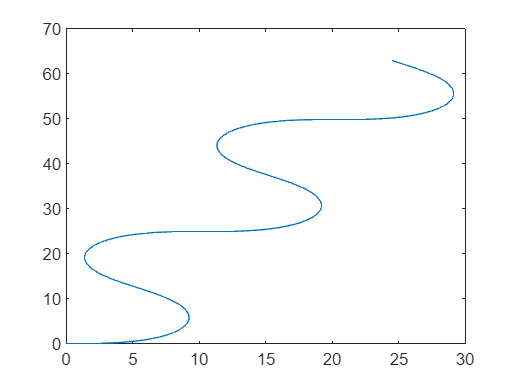

plot(xs(1,:), xs(2,:));